## State space representation

clear all
addpath("C:\Users\nicol\OneDrive\Documents\34746 - Robust & Fault Tolerent Control\Exercises\SA Tool\SaTool_3_0100\sa_tool_3_0100");
load('ECP_values.mat');
load('ECP502Data.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

s = tf('s');
%syms s
A = [0 1 0 0 0 0
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 0
    1/J_1 0
    0 0
    0 1/J_2
    0 0
    0 0];
B = B(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:)

C =      0     0     0     0     1     0



D = [0 0
     0 0
     0 0];
D=0

D = 0


G0_tf = C*inv((s*eye(size(A,1),size(A,1))-A))*B;
[a,b] = ss2tf(A,B,C,D);
sys = ss2tf(A,B,C,D);

state = ss(A,B,C,D);
G0_2 = tf(state);

%bode(G0_2)


Q_c = diag([2 0 2 0 2.5 0.0024]);
R_c = diag([10]);
K_c = lqr(A, B, Q_c, R_c);

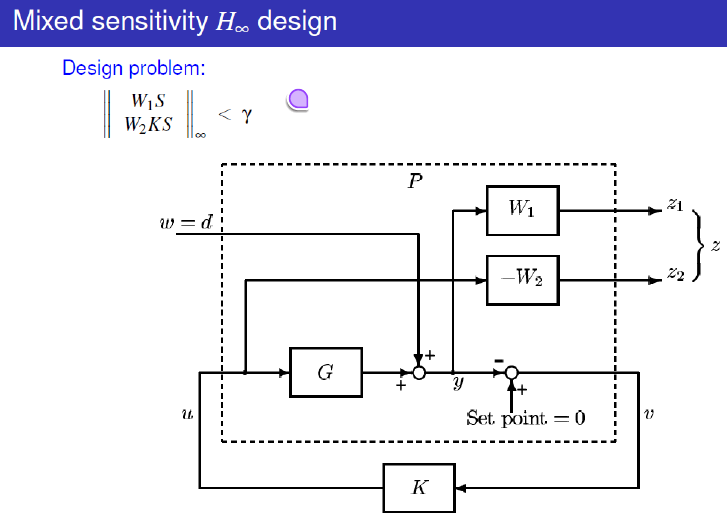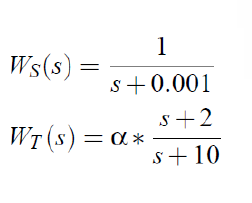

Ws = W1 

WT = W2

M = 2.5;
A = 0.1;
omega_star = (1/1.5)*2*pi;
W1 = ((s/M+omega_star)/(s+omega_star*A))^3;
W2 = W1;
[K_Hinf,Cl,Gam,Info] = mixsyn(G0_tf,W1,W2,[]); 
K_Hinf;
Gam

Gam = 0.6131

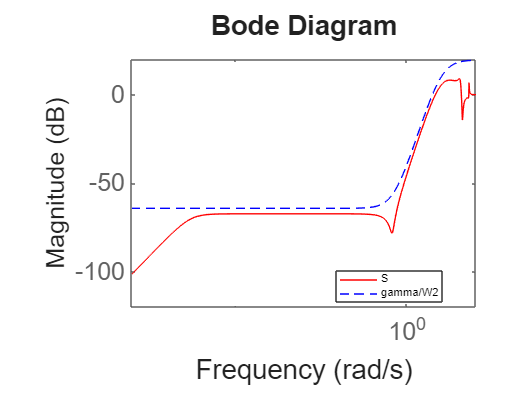

S_tf = 1/(1+G0_2*tf(K_Hinf));


figure;
bodemag(S_tf,'r',Gam/(W1),'b--');
legend('S', 'gamma/W2',Location='best');

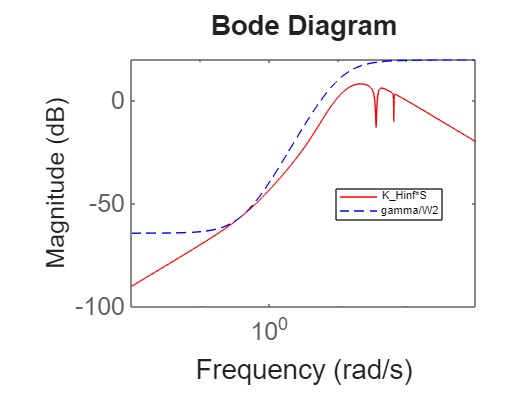

%saveas(gcf, 'figures/p2.png');
figure;
bodemag(K_Hinf*S_tf,'r',Gam/W2,'b--');
legend('K_Hinf*S', 'gamma/W2',Location='best');

%saveas(gcf, 'figures/p2.png');



